# Ordered Vaccination.

Here we will run the model with an vaccination strategy where we vaccinate the oldest age-groups first.

## Getting the `lib.classes.VaccinationRestriction` object.

First, we have to give some restrictions on our vaccination plan. This guide will follow the steps that Joost worked out.

### Computing the initialisation arguments.

The `lib.classes.VaccinationRestriction `class takes 3 input arguments:

- The Efficacy of the vaccine. *(Defaults to 1)*

- The maximum amount of vaccinations we can do per day. *(Defaults to infinite)*

- The maximum amount of vaccinations that we can to in total. *(Defaults to infinite)*

#### Efficacy

We will use the BioNTech/Pfizer vaccine, which has an Efficacy of 0.95.

Efficacy = 0.95;

#### Maximal amount of vaccinations per day.

First, off, we assume that the production of the vaccine is. Therefore, the total amount of vaccinations per year is:

vacc_production_per_year = 1.3e9;

Currently there are 590 million vaccines ordered totally. The Netherlands has ordered 3.9 million vaccines. Assuming that the produced vaccines will be distributed evenly over all the countries, we can calculate the amount of vaccines that will be available in the Netherlands per year.

vacc_ordered_total         = 590e6;
vacc_ordered_nl            = 3.9e6;
vacc_available_nl_per_year = (vacc_ordered_nl / vacc_ordered_total) * vacc_production_per_year

vacc_available_nl_per_year = 8.5932e+06

Now the  `lib.classes.VaccinationRestriction `class requires the amount of vaccinations per day, we get this just by scaling the amount of available vaccinations.

vacc_available_nl_per_day = (days(1) / years(1)) * vacc_available_nl_per_year

vacc_available_nl_per_day = 2.3527e+04

This value can be used as the second argument of our `lib.classes.VaccinationRestriction `class.

#### Maximal amount of vaccinations.

Now assume that the Netherlands only places a limited amount of orders for the vaccine, each with the same size. Then the maximal amount of vaccinations is also limited. (You can use the slider to increase the amount of oders that the Netherlands will place.)

vacc_available_nl_total = vacc_ordered_nl * 3

vacc_available_nl_total = 11700000

We now have all the variables needed to create the class.

### Initializing the VaccinationRestiction class.

We can now initialize the vaccination restictions class using the values computed above:

VR = lib.classes.VaccinationRestriction( ...
    Efficacy, ...
    vacc_available_nl_per_day, ...
    vacc_available_nl_total ...
)

VR =   VaccinationRestriction with properties:

        Efficacy: 0.9500
       MaxPerDay: 2.3527e+04
        TotalMax: 11700000
    EffMaxPerDay: 2.2351e+04
     EffTotalMax: 11115000


## Creating the ordered strategy.

Now that we have the  `lib.classes.VaccinationRestriction `instance, we can use it to generate a vaccination strategy. Currently, there is only one way to generate a strategy called *ordered*. This strategy will try to vaccinate as much people in one group first before vaccinating the next group. We can get this vaccination the following way:

 % The age groups that we will look at.
Groups = [
    "0-9"
    "10-19"
    "20-29"
    "30-39"
    "40-49"
    "50-59"
    "60-69"
    "70+"
];

 % The order in which we will vaccinate those groups, using the indices in
 % the Groups array.
vacc_order = [8 7 6 5 4 3 2 1];

% Getting the vaccination strategy.
VS = VR.generateOrderStrategy(Groups, vacc_order)

VS =      8   498

     8   498

     8   498

     8   498

     8   498

     8   498

  VaccinationStrategy with properties:

             TTable: [498×8 timetable]
           InitialV: [8×1 double]
                  n: 498
                Rho: [8×498 double]
             RhoTot: [1×498 double]
                 Nu: [8×498 double]
                  P: [8×498 double]
               Ptot: [8×1 double]
                  T: [1×498 duration]
             DeltaT: [1×497 double]
                  N: [8×1 double]
           InitialU: [8×1 double]
                  V: [8×498 double]
                  U: [8×498 double]
         DailyTable: [498×8 timetable]
         Population: [8×1 double]
    PopulationTotal: 17414593
         Boundaries: [8×2 double]
                  m: 8
      GroupCategory: [8×1 categorical]
          GroupName: [8×1 string]


Note that this vaccination strategy satisfies the restrictions that we defined in `VR`.

VR.checkMaxPerDay(VS) % Check if we don't exceed the maximal amount of vaccines per day.

ans = logical
   1


VR.checkTotalMax(VS) % Check if we don't exceed the maximum amount of vaccines that the Netherlands ordered.

ans = logical
   1


VR.checkPopLimit(VS) % Check if we don't vaccinate more people than there actually are.

ans = logical
   1


There is of course also a method which we can use to check all vaccination rates at once:

VR.check(VS) % Do all checks at once.

ans = logical
   1


### Inspecting the Vaccination Strategy.

Now that we have the vaccination strategy, let's see what it looks like!

First, we can look at Rho to see which people we will vaccinate each day.

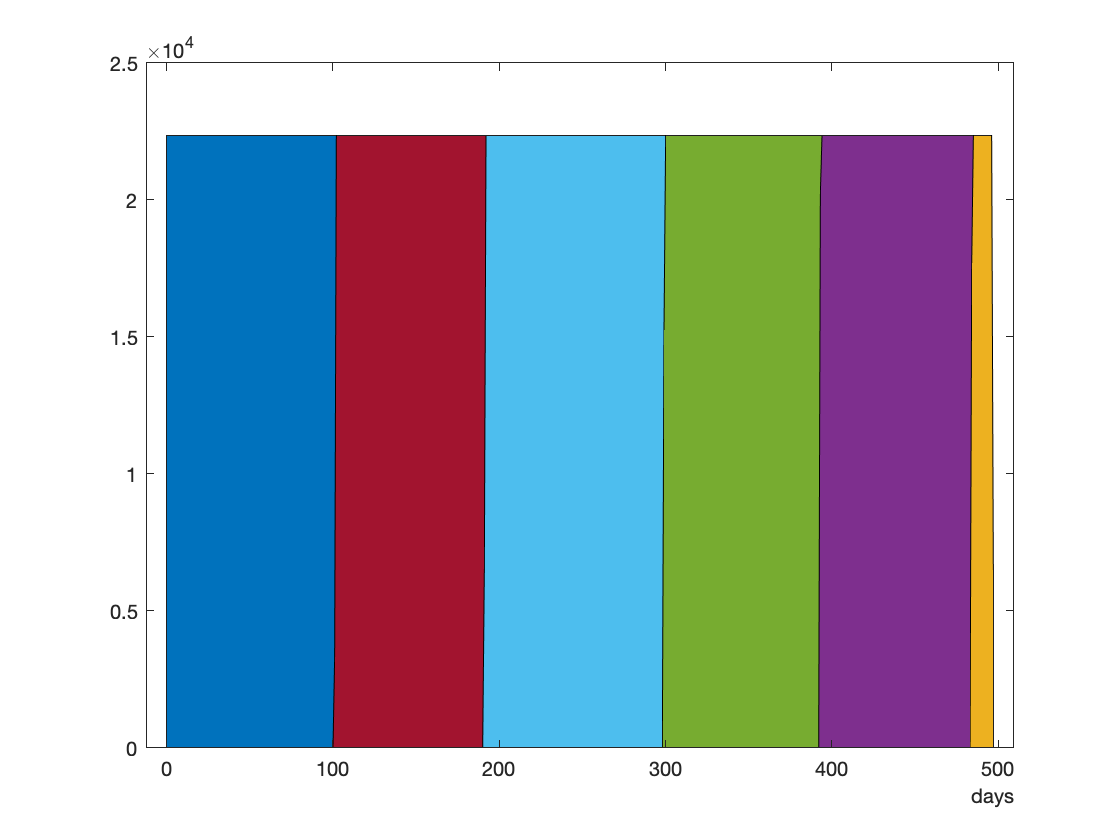

area(VS.T, VS.Rho')

As you can see, each day we vaccinate a new group.

We can also plot the amount of people that we will vaccinate before running the model (as rho is just the derivitive of V.) So let's do that real quick:

     8   498

     8   498



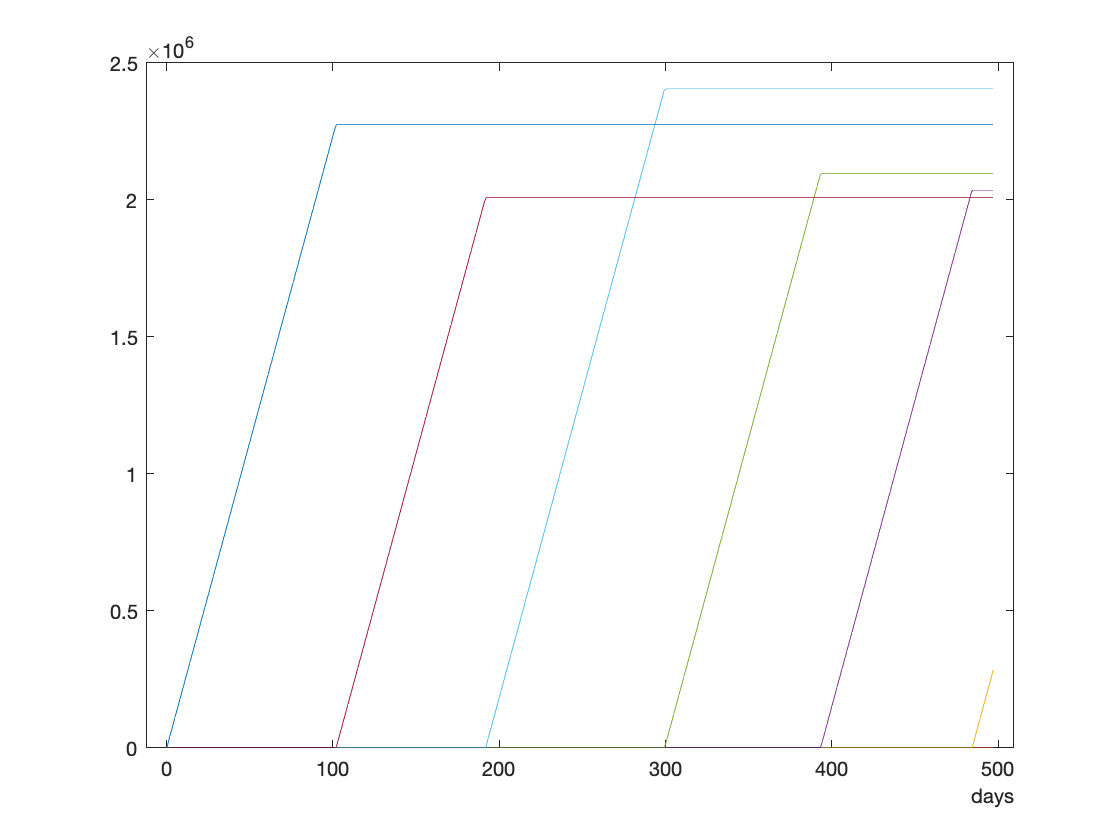

plot(VS.T, VS.V)

Finally, Nu is already calculated for us. Therefore, we can already take a sneak-peak in how it will look like when we will put it into the model.

     8   498

     8   498



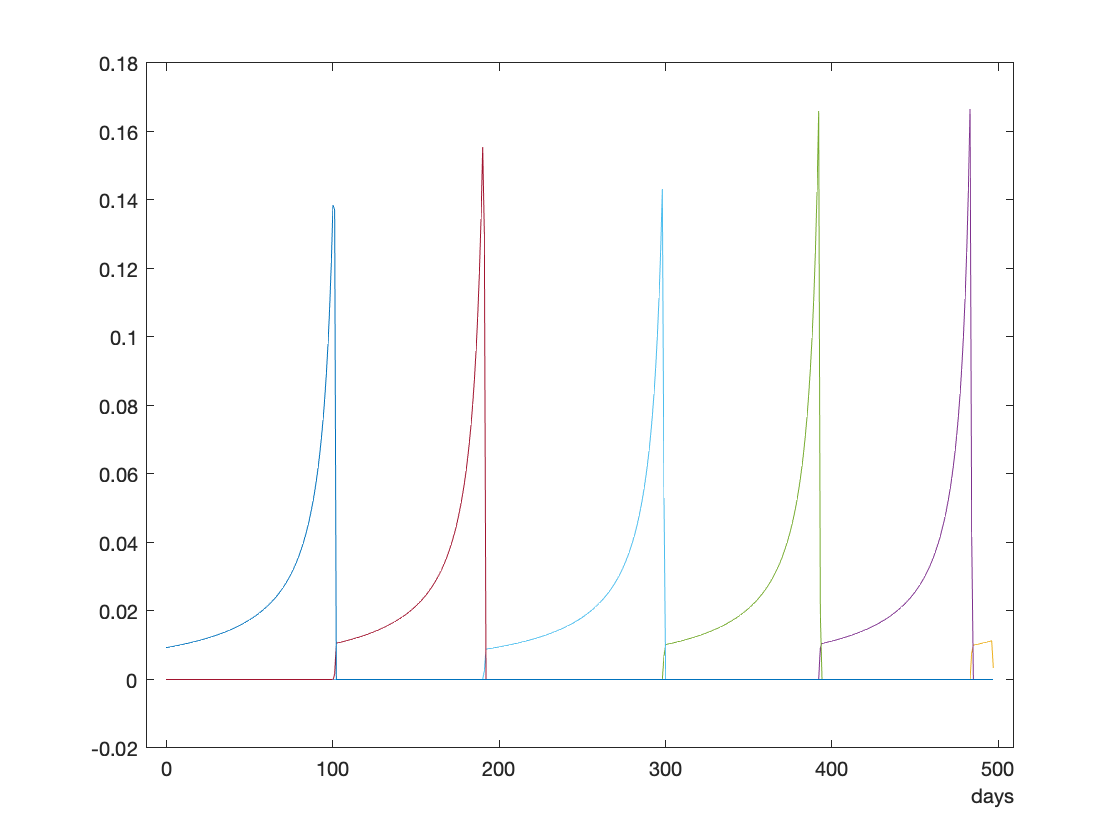

plot(VS.T, VS.Nu)

## The stategy in the model.

Now that we have the vaccination strategy, we can put it in our model. Let's set our scenario:

StartDate = "2020-11-27";
ReprNum   = 1.2;
Steps     = 300;

### Run the model.

Let's run the model by passing our values to the `lib.SIRV_model` method.

MR_vacc = lib.SIRV_model(1, ...
    'Steps', Steps, ...
    'Groups', Groups, ...
    'StartDate', StartDate, ...
    'ReprNum', ReprNum, ...
    'VaccinationStrategy', VS ...
)

MR_vacc =   DatedModelResult with properties:

          StartDate: 27-Nov-2020
               Date: [1×300 datetime]
              State: [1×300 lib.classes.ModelState]
             DeltaT: 1
             Method: EulerForward
                  n: 300
                  T: [1×300 duration]
                  N: [8×300 double]
                  S: [8×300 double]
                  I: [8×300 double]
                  R: [8×300 double]
                  U: [8×300 double]
                  V: [8×300 double]
              Alpha: [8×300 double]
                Tau: [8×300 double]
               Beta: [8×8×300 double]
                 Nu: [8×300 double]
                Rho: [8×300 double]
            SusVect: [8×300 double]
                  C: [8×8×300 double]
             P_CtoI: [8×8×300 double]
            ReprNum: [1×300 double]
            ReprEff: [1×300 double]
          SympRatio: [8×300 double]
       

We will also run the model without the vaccination strategy so that we can compare the results.

MR_no_vacc = lib.SIRV_model(1, ...
    'Steps', Steps, ...
    'Groups', Groups, ...
    'StartDate', StartDate, ...
    'ReprNum', ReprNum ...
)

MR_no_vacc =   DatedModelResult with properties:

          StartDate: 27-Nov-2020
               Date: [1×300 datetime]
              State: [1×300 lib.classes.ModelState]
             DeltaT: 1
             Method: EulerForward
                  n: 300
                  T: [1×300 duration]
                  N: [8×300 double]
                  S: [8×300 double]
                  I: [8×300 double]
                  R: [8×300 double]
                  U: [8×300 double]
                  V: [8×300 double]
              Alpha: [8×300 double]
                Tau: [8×300 double]
               Beta: [8×8×300 double]
                 Nu: [8×300 double]
                Rho: [8×300 double]
            SusVect: [8×300 double]
                  C: [8×8×300 double]
             P_CtoI: [8×8×300 double]
            ReprNum: [1×300 double]
            ReprEff: [1×300 double]
          SympRatio: [8×300 double]
    

### Analysing the results.

First, let's compare the amount of infected people side by side:

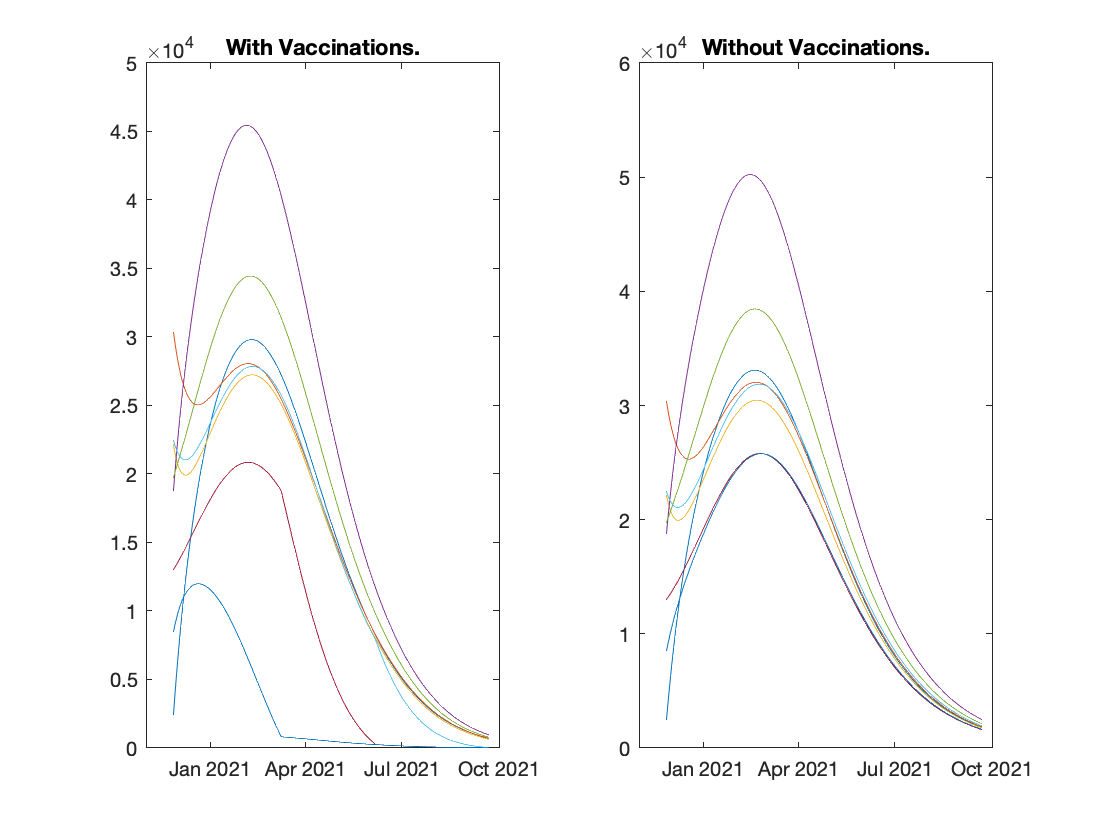

% Create new figure.
figure;

% Plot the infectious people in the scenario where we have vaccinations.
subplot(1, 2, 1);
plot(MR_vacc.Date, MR_vacc.I);
title('With Vaccinations.');

% Plot the infectious people in the scenario where we don't have
% vaccinations.
subplot(1, 2, 2);
plot(MR_no_vacc.Date, MR_no_vacc.I);
title('Without Vaccinations.');

We can than compare the results by using the functions and methods on `lib.classes.ModelResult `class:

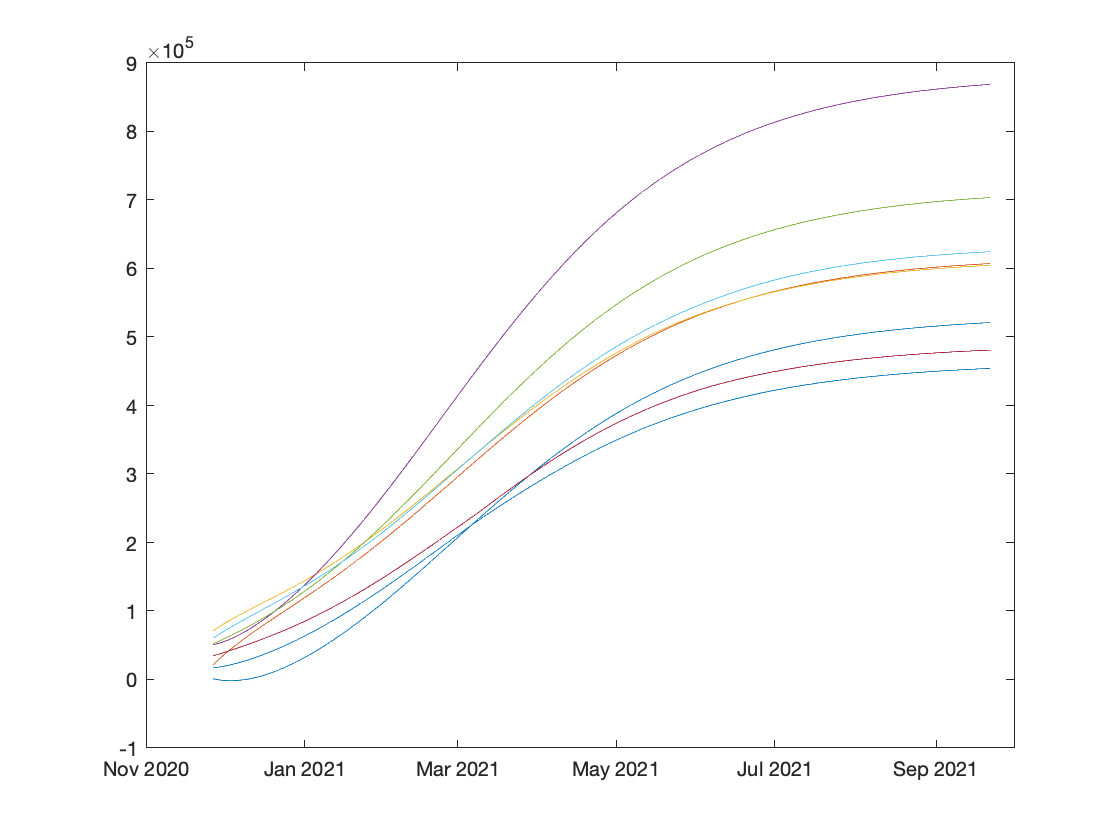

figure;
plot(MR_vacc.Date, MR_no_vacc.R - MR_vacc.I)

Or using one of the cost functions in the `+lib/+costs/ `folder to compare them.

lib.costs.total_deaths(MR_vacc)

ans = 1.8828e+04

lib.costs.total_deaths(MR_no_vacc)

ans = 6.7593e+04